# Chapter 3, Section 3 (Part 1)

The goal in this activity is to introduce what is known as a **basis** for a vector space.

**Definition:** A subset $B$ of a vector space $V$ is a **basis** for $V$ provided that:

- $B$ is a linearly independent set of vectors in $V$.

- $\text{span}(B)=V$.

# Standard Basis for $R^2$

Consider the columns of a $2\times 2$ identity matrix, which we will name $\vec e_1$ and $\vec e_2$.


$$\pmatrix{1 & 0\cr 0 & 1}=\pmatrix{\vec e_1 & \vec e_2}$$


The vectors $\vec e_1$ and $\vec e_2$ are linearly independent, since neither is a constant multiple of the other. Secondly, any vector in $R^2$ can be written as a linear combination of these two vectors. 

# Example #1

Note that


$$\pmatrix{3\cr 4}=3\pmatrix{1\cr 0}+4\pmatrix{0\cr 1}=3\vec e_1+4\vec e_2$$


$B=\left\{\vec e_1, \vec e_2\right\}$ is called the  **standard basis** for $R^2$. We can also visualize how this basis spans $R^2$. Note that $\pmatrix{3\cr 4}$ is a linear combination of $\vec e_1$ and $\vec e_2$ by using the parallelogram rule in the following image.

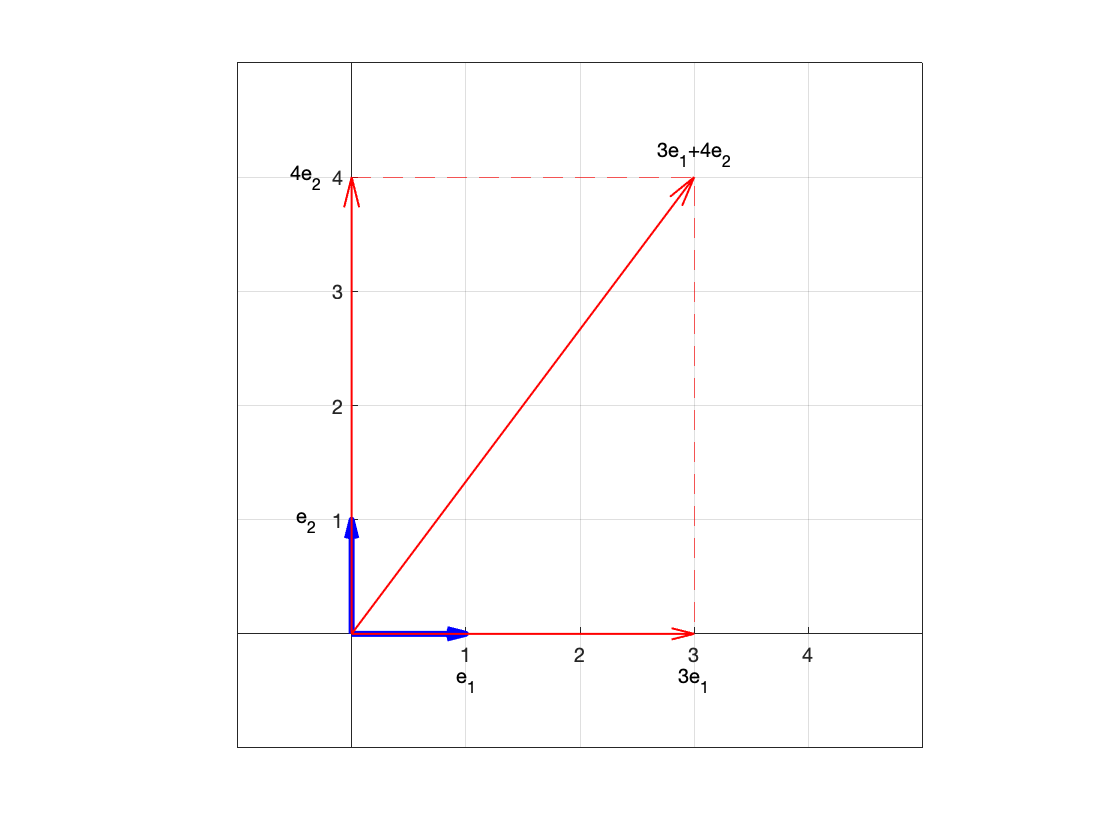

figure
quiver(0,0,1,0,0,'LineWidth',3,'Color','b','MaxHeadSize',0.5)
hold on
quiver(0,0,0,1,0,'LineWidth',3,'Color','b','MaxHeadSize',0.5)
a=3; b=4;
quiver(0,0,a,b,0,'LineWidth',1,'Color','r','MaxHeadSize',0.2)
quiver(0,0,a,0,0,'LineWidth',1,'Color','r','MaxHeadSize',0.2)
quiver(0,0,0,b,0,'LineWidth',1,'Color','r','MaxHeadSize',0.2)
line([0,a,a],[b,b,0],'LineStyle','--','Color','r')
axis equal
axis([-1,5,-1,5])
grid on
ax=gca;
ax.XAxisLocation='origin';ax.YAxisLocation='origin';
text(1,-0.4,'e_1','HorizontalAlignment','center')
text(a,-0.4,'3e_1','HorizontalAlignment','center')
text(-0.4,1,'e_2','HorizontalAlignment','center')
text(-0.4,b,'4e_2','HorizontalAlignment','center')
text(a,b+0.2,'3e_1+4e_2','HorizontalAlignment','center')
hold off

# Another Basis for $R^2$

Bases for $R^2$ are not unique. Let's look at an example.

# Example #2

Show that $B=\left\{\pmatrix{2\cr 1},\ \pmatrix{-1\cr 2}\right\}$ is a basis for $R^2$.

**Solution:** Note that $\pmatrix{2\cr 1}$ is not a constant multiple of $\pmatrix{-1\cr 2}$, so these two vectors are linearly independent. Now, can any vector $\pmatrix{a\cr b}\in R^2$ be written as a linear combination of these two vectors? Let's do a calculation to see if this is possible.


$$\begin{array}{rcl}
c_1\pmatrix{2\cr 1}+c_2\pmatrix{-1\cr 2}&=&\pmatrix{a\cr b}\\
\pmatrix{2 & -1\cr 1 & 2}\pmatrix{c_1\cr c_2}&=&\pmatrix{a\cr b}

\end{array}$$


Because the columns of this coefficient matrix are linearly independent, it is invertible, so this equation has a unique solution. Let's try $\pmatrix{a\cr b}=\pmatrix{1\cr 8}$.


$$\begin{array}{rcl}
\pmatrix{2 & -1\cr 1 & 2}\pmatrix{c_1\cr c_2}&=&\pmatrix{1\cr 8}\\
\pmatrix{c_1\cr c_2}&=&\pmatrix{2 & -1\cr 1 & 2}^{-1}\pmatrix{1\cr 8}\\
\pmatrix{c_1\cr c_2}&=&\frac{1}{5}\pmatrix{2 & 1\cr -1 & 2}\pmatrix{1\cr 8}\\
\pmatrix{c_1\cr c_2}&=&\frac15\pmatrix{10\cr 15}\\
\pmatrix{c_1\cr c_2}&=&\pmatrix{2\cr 3}
\end{array}$$


Therefore, $\pmatrix{3\cr 4}=2\pmatrix{2\cr 1}+1\pmatrix{-1\cr 2}$. Let's visualize that this is correct. Note that $\pmatrix{1\cr 8}$ is a linear combination of $\pmatrix{2\cr 1}$ and $\pmatrix{-1\cr 2}$ by using the parallelogram rule in the following image.

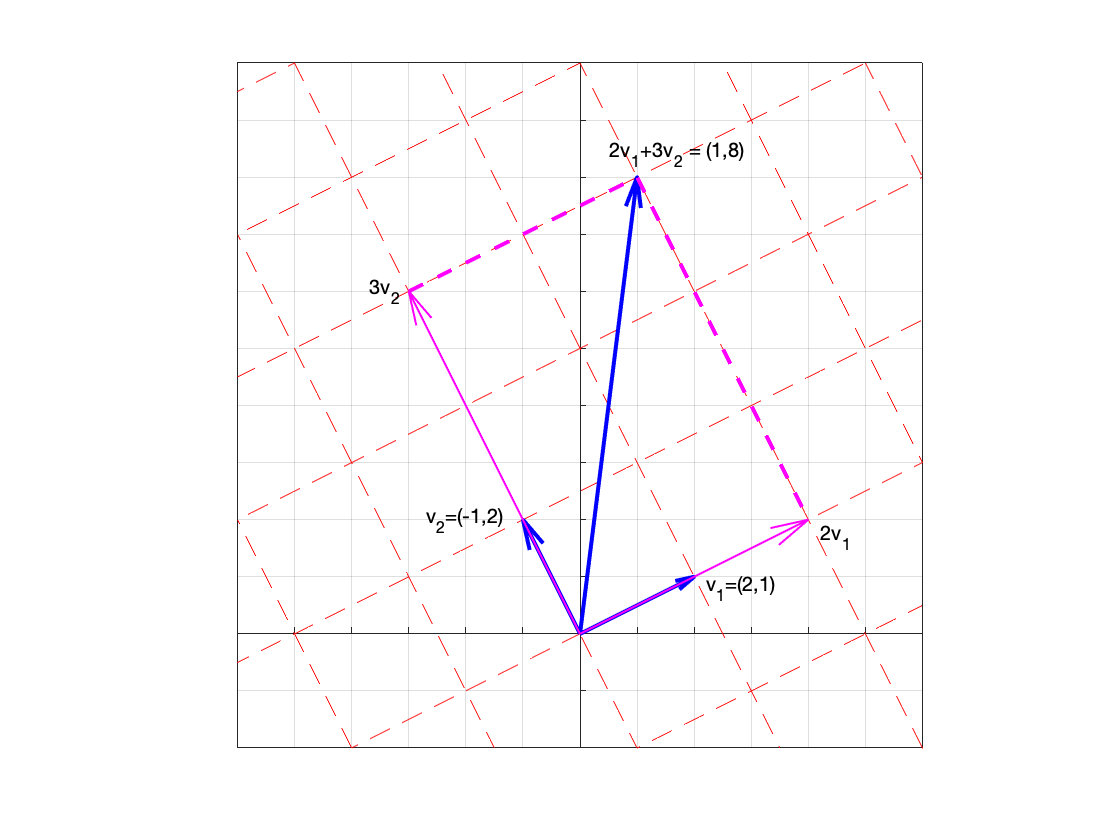

t=linspace(-6,6);
for k=-6:6
    x=2*k-t;
    y=k+2*t;
    plot(x,y,'r--')
    hold on
end
for k=-6:6
    x=-k+2*t;
    y=2*k+t;
    plot(x,y,'r--')
end
quiver(0,0,2,1,0,'LineWidth',2,'Color','b','MaxHeadSize',0.5)
quiver(0,0,-1,2,0,'LineWidth',2,'Color','b','MaxHeadSize',0.8)
quiver(0,0,1,8,0,'LineWidth',2,'Color','b','MaxHeadSize',0.2)
quiver(0,0,4,2,0,'LineWidth',1,'Color','m','MaxHeadSize',0.5)
quiver(0,0,-3,6,0,'LineWidth',1,'Color','m','MaxHeadSize',0.3)
line([-3,1,4],[6,8,2],'LineStyle','--','LineWidth',2,'Color','m')
ax=gca;
ax.XAxisLocation='origin';ax.YAxisLocation='origin';
axis equal
axis([-6,6,-2,10])
grid on
xticks(-6:6)
yticks(-2:10)
xticklabels({})
yticklabels({})
text(2.2,0.8,'v_1=(2,1)')
text(4.2,1.7,'2v_1')
text(-2.7,2,'v_2=(-1,2)')
text(-3.7,6,'3v_2')
text(0.5,8.4,'2v_1+3v_2 = (1,8)')
hold off

In fact, this image makes it clear that we can express any vector in $R^2$ as a linear combination of $\pmatrix{2\cr 1}$ and $\pmatrix{-1\cr 2}$, so $B=\left\{\pmatrix{2\cr 1},\ \pmatrix{-1\cr 2}\right\}$ is also a basis for $R^2$.

# Standard Basis for $R^3$

Consider the columns of a $3\times 3$ identity matrix, which we will name $\vec e_1$, $\vec e_2$, and $\vec e_3$.


$$\pmatrix{1 & 0 & 0\cr 0 & 1 & 0\cr 0 & 0 & 1}=\pmatrix{\vec e_1 & \vec e_2 & \vec e_3}$$


The determinant of the identity matrix is 1 (product of the diagonal elements), which is not zero, so the vectors $\vec e_1$, $\vec e_2$, and $\vec e_3$ are linearly independent. Secondly, any vector in $R^3$ can be written as a linear combination of these three vectors. 

# Example #3

For example,


$$\pmatrix{2\cr 3\cr 3}=2\pmatrix{1\cr 0\cr 0}+3\pmatrix{0\cr 1\cr 0}+3\pmatrix{0\cr 0\cr 1}=2\vec e_1+3\vec e_2+3\vec e_2$$


$B=\left\{\vec e_1, \vec e_2,  \vec e_3\right\}$ is called the  **standard basis** for $R^3$. We can also visualize that this basis works. Note that $\pmatrix{2\cr 3\cr 3}$ is a linear combination of $\vec e_1$, $\vec e_2$, and $\vec e_3$ by using the parallelepiped in the following image.

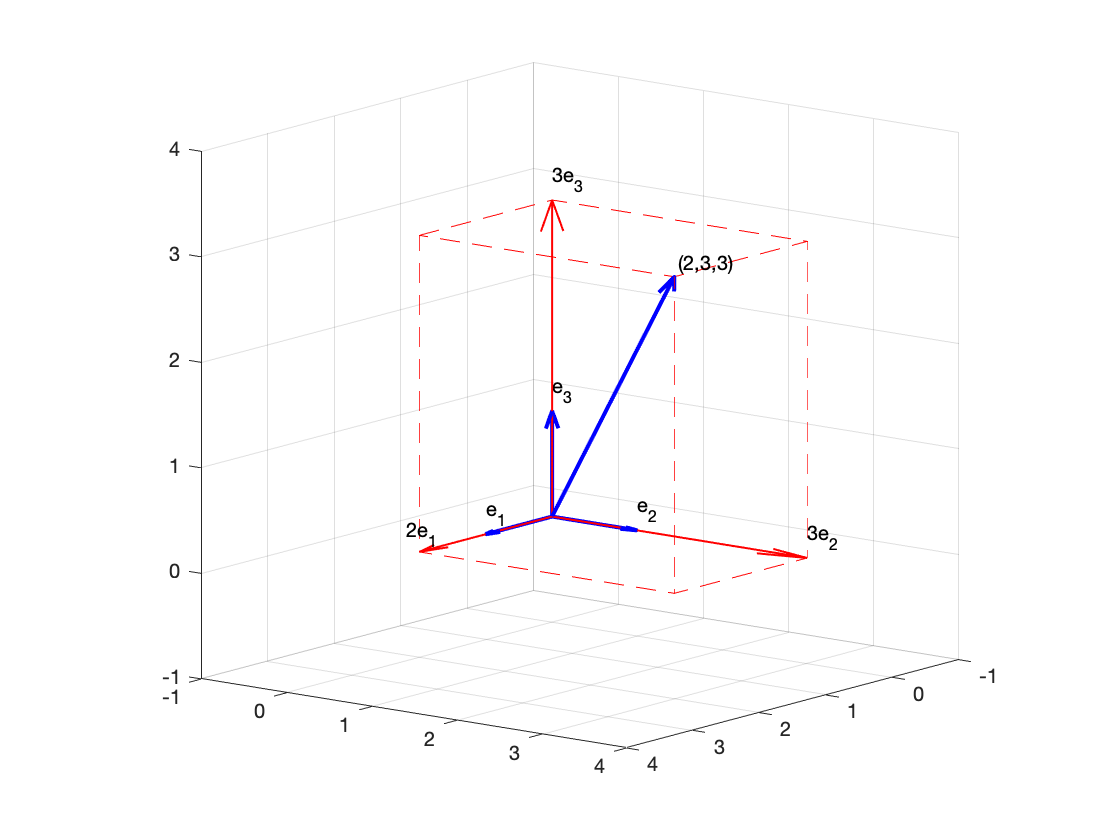

figure
quiver3(0,0,0,1,0,0,0,'LineWidth',2,'Color','b','MaxHeadSize',0.5)
hold on
quiver3(0,0,0,0,1,0,0,'LineWidth',2,'Color','b','MaxHeadSize',0.5)
quiver3(0,0,0,0,0,1,0,'LineWidth',2,'Color','b','MaxHeadSize',0.5)
quiver3(0,0,0,2,3,3,0,'LineWidth',2,'Color','b','MaxHeadSize',0.3)
quiver3(0,0,0,2,0,0,0,'LineWidth',1,'Color','r','MaxHeadSize',0.5)
quiver3(0,0,0,0,3,0,0,'LineWidth',1,'Color','r','MaxHeadSize',0.5)
quiver3(0,0,0,0,0,3,0,'LineWidth',1,'Color','r','MaxHeadSize',0.3)
line([2,2,0],[0,3,3],[0,0,0],'LineStyle','--','Color','r')
line([2,2,0,0,2],[0,3,3,0,0],[3,3,3,3,3],'LineStyle','--','Color','r')
line([2,2],[0,0],[0,3],'LineStyle','--','Color','r')
line([2,2],[3,3],[0,3],'LineStyle','--','Color','r')
line([0,0],[3,3],[0,3],'LineStyle','--','Color','r')
line([0,0],[0,0],[0,3],'LineStyle','--','Color','r')
axis square
axis ([-1,4,-1,4,-1,4])
xticks(-1:4)
yticks(-1:4)
zticks(-1:4)
text(1,0,0.2,'e_1')
text(0,1,0.2,'e_2')
text(0,0,1.2,'e_3')
text(2.2,0,0.2,'2e_1')
text(0,3,0.2,'3e_2')
text(0,0,3.2,'3e_3')
text(2.2,3.2,3.2,'(2,3,3)')
grid on
hold off
view(128,12)

# Another Basis in $R^3$

The bases for $R^3$ are not unique. Let's consider another example.

# Example #4

Show that $B=\left\{\pmatrix{2\cr 1\cr 0},\ \pmatrix{0\cr 3\cr 1},\ \pmatrix{0\cr 0\cr 3}\right\}$ is a basis for $R^3$.

**Solution:** Let's write


$$\begin{array}{rcl}
c_1\pmatrix{2\cr 1\cr 0}+c_2\pmatrix{0\cr 3\cr 1}+c_3\pmatrix{0\cr 0\cr 3}&=&\pmatrix{0\cr 0\cr 0}\\
\pmatrix{2 & 0 & 0\cr 1 & 3 & 0\cr 0 & 1 & 3}\pmatrix{c_1\cr c_2\cr c_3}&=&\pmatrix{0\cr 0\cr 0}\\

\end{array}$$


Note that our matrix is lower triangular, so the determinant is the product of its diagonal elemants, which is $(2)(3)(3)=18$. Because the determinant does not equal zero, the columns of the matrix are linearly independent. Also, because the matrix $A$ is invertible, the system $A\vec x=\vec b$ has a unique solution for all $\vec b\in R$ (that is, every vector $\vec b\in R$ can be written as a linear combination of the columns of $A$). So, $\text{span}(B)=R^3$. Therefore, 


$$B=\left\{\pmatrix{2\cr 1\cr 0},\ \pmatrix{0\cr 3\cr 1},\ \pmatrix{0\cr 0\cr 3}\right\}$$


 is a basis for $R^3$.  Let's visualize this. Can $(2,-5,4)$ be written as a linear combination of the basis vectors?


$$\begin{array}{rcl}
c_1\pmatrix{2\cr 1\cr 0}+c_2\pmatrix{0\cr 3\cr 1}+c_3\pmatrix{0\cr 0\cr 3}&=&\pmatrix{2\cr -5\cr 4}\\
\pmatrix{2 & 0 & 0\cr 1 & 3 & 0\cr 0 & 1 & 3}\pmatrix{c_1\cr c_2\cr c_3}&=&\pmatrix{2\cr -5\cr 4}
\end{array}$$


This gives us a system of three linear equations:


$$\begin{array}{rcl}
2c_1&=&2\\
c_1+3c_2&=&-5\\
c_2+3c_3&=&4
\end{array}$$


Because our coefficient matrix is lower triangular, we can use forward substitution to solve this system. Solving the first equation gives us $c_1=1$. Substituting $c_1=1$ in the second equation gives us:


$$\begin{array}{rcl}
1+3c_2&=&-5\\
3c_2&=&-6\\
c_2&=&-2
\end{array}$$


Substituting $c_2=-2$ in the third equation gives us:


$$\begin{array}{rcl}
-2+3c_3&=&4\\
3c_3&=&6\\
c_3&=&2
\end{array}$$


Therefore, $c_1=1$, $c_2=-2$, and $c_3=2$, which means


$$\pmatrix{2\cr -5\cr 4}=1\pmatrix{2\cr 1\cr0}-2\pmatrix{0\cr 3\cr 1}+2\pmatrix{0\cr 0\cr 3}$$


Now we can visualize that this works with the parallelepiped method.

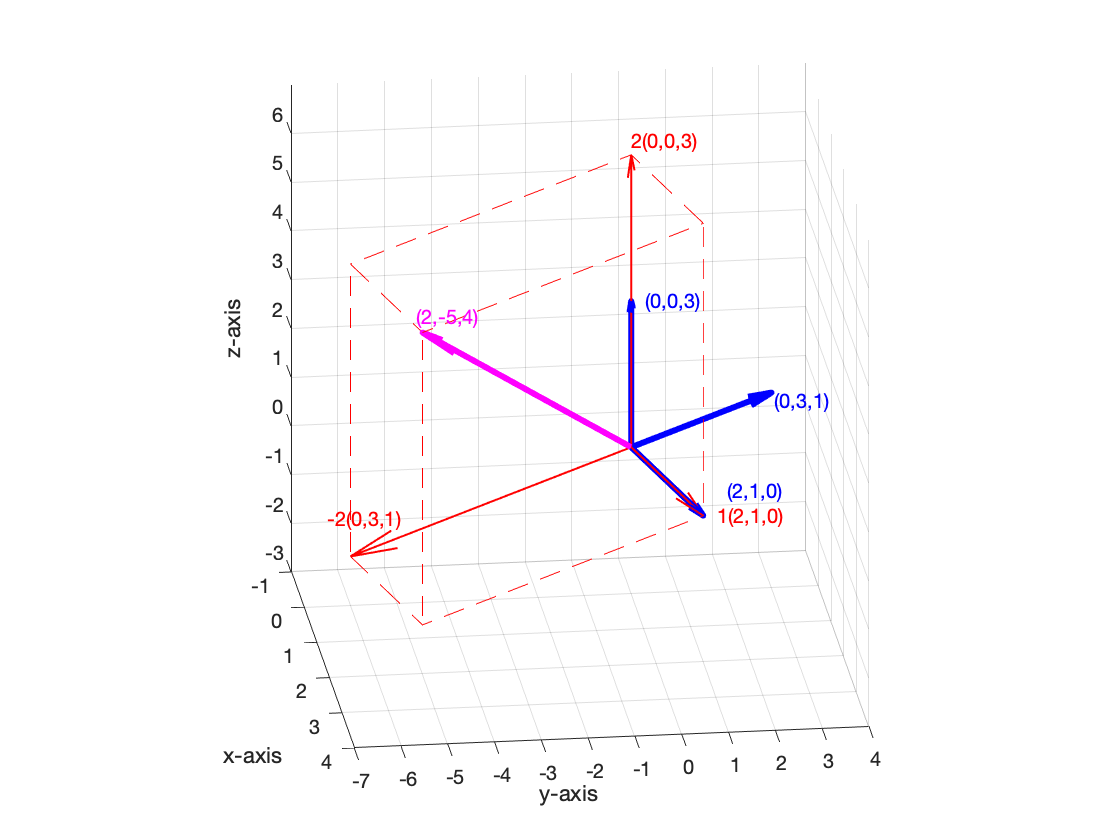

figure
quiver3(0,0,0,2,1,0,0,'LineWidth',3,'Color','b','MaxHeadSize',0.5)
hold on
quiver3(0,0,0,0,3,1,0,'LineWidth',3,'Color','b','MaxHeadSize',0.5)
quiver3(0,0,0,0,0,3,0,'LineWidth',3,'Color','b','MaxHeadSize',0.2)
quiver3(0,0,0,2,-5,4,0,'LineWidth',3,'Color','m','MaxHeadSize',0.5)
quiver3(0,0,0,2,1,0,0,'LineWidth',1,'Color','r','MaxHeadSize',1)
quiver3(0,0,0,0,-6,-2,0,'LineWidth',1,'Color','r','MaxHeadSize',0.5)
quiver3(0,0,0,0,0,6,0,'LineWidth',1,'Color','r','MaxHeadSize',0.2)
line([2,2,0],[1,-5,-6],[0,-2,-2],'LineStyle','--','Color','r')
line([2,2,0,0,2],[1,-5,-6,0,1],[6,4,4,6,6],'LineStyle','--','Color','r')
line([2,2],[1,1],[0,6],'LineStyle','--','Color','r')
line([2,2],[-5,-5],[-2,4],'LineStyle','--','Color','r')
line([0,0],[-6,-6],[-2,4],'LineStyle','--','Color','r')
line([0,0],[0,0],[0,3],'LineStyle','--','Color','r')
axis square
axis ([-1,4,-7,4,-3,7])
xticks(-1:4)
yticks(-7:4)
zticks(-3:7)
text(0.2,3,1,'(0,3,1)','Color','b')
text(0,0.3,3,'(0,0,3)','Color','b')
text(2,1.3,0,'1(2,1,0)','Color','r')
text(2,1.5,.5,'(2,1,0)','Color','b')
text(0,-6.5,-1.2,'-2(0,3,1)','Color','r')
text(0,0,6.3,'2(0,0,3)','Color','r')
text(2.2,-5.2,4.5,'(2,-5,4)','Color','m')
grid on
xlabel('x-axis')
ylabel('y-axis')
zlabel('z-axis')
hold off
view(83,20)

The three basis vectors are drawn and labeled in the color blue. The linear combination $(2,-5,4)$ is drawn and labeled in the color magenta. Note that $(2,-5,4)$ is the linear combination (parallelepiped method) of the three vectors $(1,2,0)-2(0,3,1)+2(0,0,3)$, drawn and labeled in red. Note that because we multiplied $(0,3,1)$ by $-2$, the vector $-2(0,3,1)$ is twice as long, but pointing in the opposite direction.

# Standard Basis for $R^n$

We've seen that $B=\left\{\pmatrix{1\cr 0},\ \pmatrix{0\cr 1}\right\}$ is the standard basis for $R^2$ and $B=\left\{\pmatrix{1\cr 0\cr 0},\ \pmatrix{0\cr 1\cr 0},\ \pmatrix{0\cr 0\cr 1}\right\}$ is the standard basis for $R^3$. Similarly $B=\left\{\pmatrix{1\cr 0\cr 0\cr 0},\ \pmatrix{0\cr 1\cr 0\cr 0},\ \pmatrix{0\cr 0\cr 1\cr 0},\ \pmatrix{0\cr 0\cr 0\cr 1}\right\}$ is the standard basis for $R^4$. In each case, if we join these vectors as the columns of a matrix, we get the identity matrix. 

eye(5)

ans =      1     0     0     0     0
     0     1     0     0     0
     0     0     1     0     0
     0     0     0     1     0
     0     0     0     0     1


The columns of this matrix are the basis for $R^5$. In general, the standard basis for $R^n$ is $B=\left\{\vec e_1,\ \vec e_2,\ \vec e_3,\ \ldots,\ \vec e_n\right\}$ , where $\vec e_1,\ \vec e_2,\ \vec e_3,\ \ldots,\ \vec e_n$ are the columns of an $n\times n$ identity matrix.

# Example #5

Show that


$$S=\left\{\pmatrix{1 & 0\cr 2 & 1},\ \pmatrix{2 & 1\cr 0 & 1},\ \pmatrix{0 & 1\cr 2 & 1},\ \pmatrix{2 & 1\cr 1 & 0}\right\}$$


is a basis for $M_{2\times 2}$, the set of all $2\times 2$ matrices.

**Solution:** Can any matrix in $M_{2\times 2}$ be written as a linear combination of the matrices in $S$?


$$\begin{array}{rcl}
c_1\pmatrix{1&0\cr 2 & 1}+c_2\pmatrix{2 & 1\cr 0 & 1}+c_3\pmatrix{0 & 1\cr 2 & 1}+c_4\pmatrix{2 & 1\cr 1 & 0}&=&\pmatrix{a & b\cr c & d}\\
\pmatrix{c_1+2c_2+2c_4 & c_2+c_3+c_4\cr 2c_1+2c_3+c_4 & c_1+c_2+c_3}&=&\pmatrix{a & b\cr c & d}\\
\end{array}$$


This gives us a linear system of four equations in four unknowns.


$$\begin{array}{rcl}
c_1+2c_2+2c_4&=&a\\
c_2+c_3+c_4&=&b\\
2c_1+2c_3+c_4&=&c\\
c_1+c_2+c_3&=&d
\end{array}$$


Let's use Matlab to check this step.

syms c1 c2 c3 c4 a b c d
M1=[1 0;2 1]; M2=[2 1;0 1]; M3=[0 1;2 1]; M4=[2 1;1 0]; M=[a b;c d];
eqns=c1*M1+c2*M2+c3*M3+c4*M4==M

$$eqns = \left(\begin{array}{cc} c_{1}+2\,c_{2}+2\,c_{4}=a & c_{2}+c_{3}+c_{4}=b\\ 2\,c_{1}+2\,c_{3}+c_{4}=c & c_{1}+c_{2}+c_{3}=d \end{array}\right)$$

Same as our hand-calculations. Now, set up the augmented matrix and row reduce.


$$\pmatrix{1 & 2 & 0 & 2 & a\cr 0 & 1 & 1 & 1 & b\cr 2 & 0 & 2 & 1 & c\cr 1 & 1 & 1 & 0 & d}\ \matrix{~\cr ~ \cr R_3-2R_1\cr R_4-R_1}\qquad\longrightarrow\qquad\pmatrix{1 & 2 & 0 & 2 & a\cr 0 & 1 & 1 & 1 & b\cr 0 & -4 & 2 & -3 & c-2a\cr 0 & -1 & 1 & -2 & d-a}$$


We can check this with Matlab.

A=[1 2 0 2 a;0 1 1 1 b;2 0 2 1 c;1 1 1 0 d];
r1=A(1,:);
r2=A(2,:);
r3=A(3,:);
r4=A(4,:);
A=[r1;r2;r3-2*r1;r4-r1]

$$A = \left(\begin{array}{ccccc} 1 & 2 & 0 & 2 & a\\ 0 & 1 & 1 & 1 & b\\ 0 & -4 & 2 & -3 & c-2\,a\\ 0 & -1 & 1 & -2 & d-a \end{array}\right)$$

Same as our hand-calculations. Next,


$$\pmatrix{1 & 2 & 0 & 2 & a\cr 0 & 1 & 1 & 1 & b\cr 0 & -4 & 2 & -3 & c-2a\cr 0 & -1 & 1 & -2 & d-a}\ \matrix{~\cr ~ \cr R_3+4R_2\cr R_4+R_2}\qquad\longrightarrow\qquad\pmatrix{1 & 2 & 0 & 2 & a\cr 0 & 1 & 1 & 1 & b\cr 0 & 0 & 6 & 1 & c+4b-2a\cr 0 & 0 & 2 & -1 & d+b-a}$$


We can check this with Matlab.

r1=A(1,:);
r2=A(2,:);
r3=A(3,:);
r4=A(4,:);
A=[r1;r2;r3+4*r2;r4+r2]

$$A = \left(\begin{array}{ccccc} 1 & 2 & 0 & 2 & a\\ 0 & 1 & 1 & 1 & b\\ 0 & 0 & 6 & 1 & 4\,b-2\,a+c\\ 0 & 0 & 2 & -1 & b-a+d \end{array}\right)$$

Same answer. Next,


$$\pmatrix{1 & 2 & 0 & 2 & a\cr 0 & 1 & 1 & 1 & b\cr 0 & 0 & 6 & 1 & c+4b-2a\cr 0 & 0 & 2 & -1 & d+b-a}\ \matrix{~\cr ~ \cr ~\cr R_4-(1/3)R_3}\qquad\longrightarrow\qquad\pmatrix{1 & 2 & 0 & 2 & a\cr 0 & 1 & 1 & 1 & b\cr 0 & 0 & 6 & 1 & c+4b-2a\cr 0 & 0 & 0 & -4/3 & d-(1/3)c-(1/3)b-(1/3)a}$$


We can check this with Matlab.

r1=A(1,:);
r2=A(2,:);
r3=A(3,:);
r4=A(4,:);
A=[r1;r2;r3;r4-1/3*r3]

$$A = \left(\begin{array}{ccccc} 1 & 2 & 0 & 2 & a\\ 0 & 1 & 1 & 1 & b\\ 0 & 0 & 6 & 1 & 4\,b-2\,a+c\\ 0 & 0 & 0 & -\frac{4}{3} & d-\frac{b}{3}-\frac{c}{3}-\frac{a}{3} \end{array}\right)$$

Same answer. Because we have a pivot in each column representing $c_1$, $c_2$, $c_3$, and $c_4$, any $2\times 2$ matrix can be written as a linear combination of the matrices in $S$; that is, $\text{span}(S)=M_{2\times 2}$.

To determine linear independence, we start with


$$\begin{array}{rcl}
c_1\pmatrix{1&0\cr 2 & 1}+c_2\pmatrix{2 & 1\cr 0 & 1}+c_3\pmatrix{0 & 1\cr 2 & 1}+c_4\pmatrix{2 & 1\cr 1 & 0}&=&\pmatrix{0 & 0\cr 0 & 0}\\
\pmatrix{c_1+2c_2+2c_4 & c_2+c_3+c_4\cr 2c_1+2c_3+c_4 & c_1+c_2+c_3}&=&\pmatrix{0 & 0 \cr 0 & 0}\\
\end{array}$$


This gives us a linear system of four equations in four unknowns.


$$\begin{array}{rcl}
c_1+2c_2+2c_4&=&0\\
c_2+c_3+c_4&=&0\\
2c_1+2c_3+c_4&=&0\\
c_1+c_2+c_3&=&0
\end{array}$$


This gives us the augmented matrix,


$$\pmatrix{1 & 2 & 0 & 2 & 0\cr 0 & 1 & 1 & 1 & 0\cr 2 & 0 & 2 & 1 & 0\cr 1 & 1 & 1 & 0 & 0}$$


which is identical to our starting augmented matrix above we we replace the column with $a$, $b$,  $c$, and $d$ with a columns of zeros. Therefore, if we do the exact same row operations as we did above, we will get:


$$\pmatrix{1 & 2 & 0 & 2 & 0\cr 0 & 1 & 1 & 1 & 0\cr 0 & 0 & 6 & 1 & 0\cr 0 & 0 & 0 & -4/3 & 0}$$


Again, a pivot in each of the first four columns, so the only solution is the trivial solution $c_1=c_2=c_3=c_4=0$, so the matrices in $S$ are linearly independent. Therefore, we have shown that $B$ is a basis for $M_{2\times 2}$.

# Standard Basis for $M_{2\times 2}$

Here is what is known as the standard basis for $M_{2\times 2}$.


$$B=\left\{\pmatrix{1 & 0\cr 0 & 1},\ \pmatrix{0 & 1\cr 0 & 0},\ \pmatrix{0 & 0\cr 1 & 0},\ \pmatrix{0 & 0\cr 0 & 1}\right\}$$


This is quite similar to the standard bases for $R^2$ and $R^3$ that we showed above. We'll leave it to our readers to verify that this is a basis for $M_{2\times 2}$ (it's easy).

# Example #6

Show that $B=\left\{x+2,\ x^2+1,\ x^2-x\right\}$ is a basis for $P_2$.

**Solution:** $P_2$ is the vector space of polynomials have degree $n\le 2$ Our first step is to show that $p(x)=a_0+a_1x+a_2x^2$ can be written as a linear combination of the polynomials in $B$.


$$\begin{array}{rcl}
c_1(x+1)+c_2(x^2+1)+c_3(x^2-x)&=&a_0+a_1x+a_2x^2\\
c_1x+2c_1+c_2x^2+c_2+c_3x^2-c_3x&=&a_0+a_1x+a_2x^2\\
(2c_1+c_2)+(c_1-c_3)x+(c_2+c_3)x^2&=&a_0+a_1x+a_2x^2
\end{array}$$


The only way that two polynomials can be equal for all values of $x$ is if each of the corresponding coefficients are equal. Therefore, this leads to the following system of linear equations.


$$\begin{array}{rcl}
2c_1+c_2&=&a_0\\
c_1-c_3&=&a_1\\
c_2+c_3&=&a_2
\end{array}$$


We can check this with Matlab.

syms c1 c2 c3 a0 a1 a2 x
p1=x+2; p2=x^2+1; p3=x^2-x; p=a0+a1*x+a2*x^2;
eqns=coeffs(c1*p1+c2*p2+c3*p3,x)==[a0, a1, a2]

$$eqns = \left(\begin{array}{ccc} 2\,c_{1}+c_{2}=a_{0} & c_{1}-c_{3}=a_{1} & c_{2}+c_{3}=a_{2} \end{array}\right)$$

Same equations. Now we can set up the augmented matrix and row reduce.


$$\pmatrix{2 & 1 & 0 & a_0\cr 1 & 0 & -1 & a_1\cr 0 & 1 & 1 & a_2}\ \matrix{~\cr R_2-(1/2)R_1\cr ~}\qquad\longrightarrow\qquad\pmatrix{2 & 1 & 0 & a_0\cr 0 & -1/2 & -1 & a_1-(1/2)a_0\cr 0 & 1 & 1 & a_2}$$


We can check this with Matlab.

A=[2 1 0 a0;1 0 -1 a1;0 1 1 a2];
r1=A(1,:);
r2=A(2,:);
r3=A(3,:);
A=[r1;r2-1/2*r1;r3]

$$A = \left(\begin{array}{cccc} 2 & 1 & 0 & a_{0}\\ 0 & -\frac{1}{2} & -1 & a_{1}-\frac{a_{0}}{2}\\ 0 & 1 & 1 & a_{2} \end{array}\right)$$

Same answer. Next,


$$\pmatrix{2 & 1 & 0 & a_0\cr 0 & -1/2 & -1 & a_1-(1/2)a_0\cr 0 & 1 & 1 & a_2}\ \matrix{~\cr ~\cr R_3+2R_2}\qquad\longrightarrow\qquad\pmatrix{2 & 1 & 0 & a_0\cr 0 & -1/2 & -1 & a_1-(1/2)a_0\cr 0 & 0 & -1 & a_2+2a_1-a_0}$$


We can check this with Matlab.

r1=A(1,:);
r2=A(2,:);
r3=A(3,:);
A=[r1;r2;r3+2*r2]

$$A = \left(\begin{array}{cccc} 2 & 1 & 0 & a_{0}\\ 0 & -\frac{1}{2} & -1 & a_{1}-\frac{a_{0}}{2}\\ 0 & 0 & -1 & 2\,a_{1}-a_{0}+a_{2} \end{array}\right)$$

Same answer. Note that we have a pivot in each of the first three columns representing $c_1$, $c_2$, and $c_3$, so the system is consistent. Therefore $\text{span}(B)=P_2$. 

To examine the dependence, we recognize that the zero polynomial in $P_2$ is $p(x)=0+0x+0x^2$, then set up almost the same system again.


$$\begin{array}{rcl}
c_1(x+1)+c_2(x^2+1)+c_3(x^2-x)&=&0+0x+0x^2\\
c_1x+2c_1+c_2x^2+c_2+c_3x^2-c_3x&=&0+0x+0x^2\\
(2c_1+c_2)+(c_1-c_3)x+(c_2+c_3)x^2&=&0+0x+0x^2
\end{array}$$


Therefore, this leads to the following system of linear equations.


$$\begin{array}{rcl}
2c_1+c_2&=&0\\
c_1-c_3&=&0\\
c_2+c_3&=&0
\end{array}$$


So the only difference between this augmented matrix and the one above is the fact that the last column will be a column of zeros.


$$\pmatrix{2 & 1 & 0 & 0\cr 1 & 0 & -1 & 0\cr 0 & 1 & 1 & 0}$$


So the same elementary row operations we used above will lead to this matrix. 


$$\pmatrix{2 & 1 & 0 & 0\cr 0 & -1/2 & -1 & 0\cr 0 & 0 & -1 & 0}$$


Because we have a pivot in each of the first three columns, the solution is $c_1=c_2=c_3=0$, so our linear combination


$$\begin{array}{rcl}
c_1(x+1)+c_2(x^2+1)+c_3(x^2-x)&=&0+0x+0x^2
\end{array}$$


has only the trivial solution, so the polynomials in $B$ are linearly independent. Therefore*,* $B=\left\{x+2,\ x^2+1,\ x^2-x\right\}$ is a basis for $P_2$. Note that this basis for $P_2$ has three polynomials.

# Standard Basis for $P_n$

The collection $B=\left\{1, x, x^2, x^3, \ldots, x^n\right\}$ is called the **standard basis** for $P_n$. Note that it has $n+1$ polynomials. 